%Inhomogeneous second order linear ODE example
clear

%declaring symbolic variables
syms x(t) dx(t)

%declaring ode
ode = diff(x,t,2) + 400*x == -10

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+400\,x\left(t\right)=-10$$


%declaring initial conditions
dx(t) = diff(x,t) %generate derivate as variable

$$dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$

IC = [x(0)==0.15 dx(0)==0]

$$IC = \left(\begin{array}{cc} x\left(0\right)=\frac{3}{20} & \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$


%general solution
dsolve(ode)

$$ans = C_{1}\,\cos\left(20\,t\right)-C_{2}\,\sin\left(20\,t\right)-\frac{1}{40}$$


%particular solution
sol = dsolve(ode,IC)

$$sol = \frac{7\,\cos\left(20\,t\right)}{40}-\frac{1}{40}$$

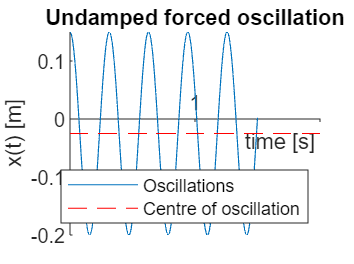


%plotting soolition
fplot(sol,[0 1.5])
hold on %plotting on same graph

%plotting centre of oscillation
fplot(-1/40, [0 2],"--r")

hold off

%beautifying plot
ax = gca;
ax.XAxisLocation ="origin";
ax.YAxisLocation ="origin";
box off

%labelling grap
xlabel("time [s]")
ylabel("x(t) [m]")
title("Undamped forced oscillation")
legend("Oscillations","Centre of oscillation","Location","southeast")

clear all

%declaring symbolic vars
syms x(t) dx(t) w sol(t)

%declaring coefficients
M = 1;
a = 0;
k = 400;

%declaring ODE
ode = M*diff(x,t,2) + a*diff(x,t) + k*x == sin(w*t)

%declaring initial conditions
dx(t) = diff(x,t);
IC = [x(0)==0 dx(0)==0];

assume(t >= 0) %time is positive

%solving differential equation
msol = dsolve(ode,IC)

%declaring my pen and paper solution
sol(t) = (1/(400-w^2)) * (sin(w*t) - (w/20)*sin(20*t))

%confirming solutions mathc
simplify(msol-sol(t))

%setting value of w
for i=19.5
    fplot(subs(sol,w,i)) %plotting function with set value of w
    
    hold on %plotting on same graph
end

%setting limits
xlim([0 40])
ylim([-0.1 0.1])

%beautifying curve
ax = gca;
ax.XAxisLocation = "Origin";
ax.YAxisLocation = "Origin";

hold off

%Week 17 question 2)
clear

%declaring symbolic variabiables
syms y(t) dy(t) w sol(t)

%declaring ode
ode = diff(y,t,2) + 7*y == 11*sin(w*t)

%time is positive
assume (t>=0)

%declaring initial conditions
dy(t) = diff(y,t)
IC = [y(0)==-0.3 dy(0)==1.2]

dsolve(ode) %general solution
matsol = dsolve(ode,IC) %particular solition

%pen and paper solution
sol(t) = (1/sqrt(7))*(1.2-((11*w)/(7-(w^2))))*sin((sqrt(7))*t) - 0.3*cos((sqrt(7))*t) + (11/(7-(w^2)))*sin(w*t)

simplify(matsol - sol)

%Year 3 PM Portfolio 1 Question 3 answer checking
clear all

%declaring symbolic variables
syms x(t)

%declaring ode
ode = diff(x,t,2) + 2*diff(x,t) + 5*x == 2*cos(2*t)*exp(-t)

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,\frac{\partial }{\partial t}x\left(t\right)+5\,x\left(t\right)=2\,\cos\left(2\,t\right)\,{\mathrm{e}}^{-t}$$


%time is positive
assume (t>0);

%attempting to find general solution
sol = dsolve(ode);

%simplifying solution
simplify(sol)

$$ans = \frac{{\mathrm{e}}^{-t}\,\left(\cos\left(2\,t\right)+2\,t\,\sin\left(2\,t\right)+4\,C_{1}\,\cos\left(2\,t\right)-4\,C_{2}\,\sin\left(2\,t\right)\right)}{4}$$